# 第2章 离散时间信号和系统分析基础

## 2.3 离散时间信号的表示及运算规则

### 2.3.3 常用的典型序列

#### `Ch2_3_3`

#### 示例1: 绘出单位采样序列

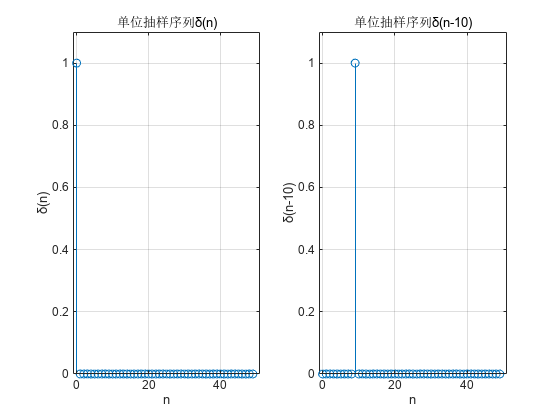

n=50;
x=zeros(1,n);
x(1)=1;
xn=0:n-1;
subplot(121);
stem(xn,x);
grid on     
axis([-1 51 0 1.1]);
title('单位抽样序列δ(n)')
ylabel('δ(n)');
xlabel('n');
k=10;
x(k)=1;
x(1)=0;
subplot(122);
stem(xn,x);
grid on     
axis([-1 51 0 1.1]);
title('单位抽样序列δ(n-10)')
ylabel('δ(n-10)');
xlabel('n');

#### 示例2: 绘出单位阶跃序列

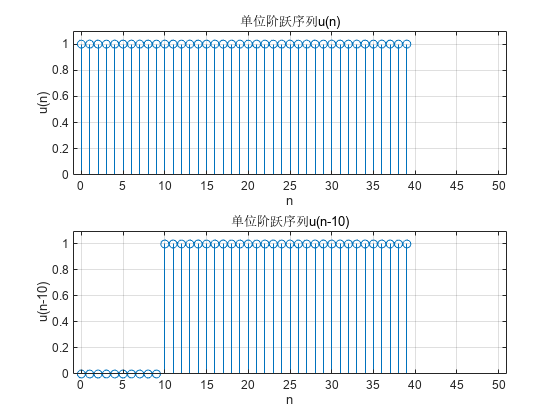

n=40;
x=ones(1,n);
xn=0:n-1;
subplot(211);
stem(xn,x);
grid on     
axis([-1 51 0 1.1]);
title('单位阶跃序列u(n)')
ylabel('u(n)');
xlabel('n');

x=[zeros(1,10),1,ones(1,29)];
subplot(212);
stem(xn,x);
grid on     
axis([-1 51 0 1.1]);
title('单位阶跃序列u(n-10)')
ylabel('u(n-10)');
xlabel('n');

#### 示例3: 绘出正弦序列


$$\begin{array}{l}
\textrm{定义：}\\
x\left(t\right)=\textrm{Asin}\left(2\pi \;f*t+\theta \right)\\
x\left(\textrm{nT}\right)=\textrm{Asin}\left(2\pi \;f*\textrm{nT}+\theta \right)\\
x\left(n\right)=\textrm{Asin}\left(2\pi \;f/F_s *n+\theta \right)\\
\textrm{程序：}\\
x=A*\sin \left(2*\textrm{pi}*f_0 /F_s *n+\textrm{theta}\right)
\end{array}$$


试用Matlab绘制$x\left(n\right)=\sin \left(\frac{n\pi }{5}\right)$的波形图

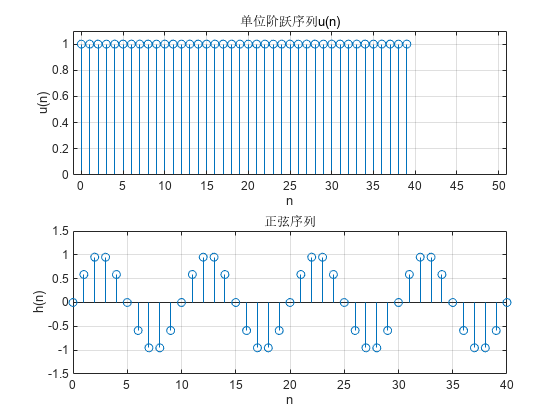

clear
n=0:59; 
x=sin(pi/5*n);
stem(n,x);
xlabel('n')
ylabel('h(n)')
title('正弦序列')
axis([0,40,-1.5,1.5]);
grid on;